# Proximal Algorithm for Discrete Optimal Transport

The following code aims to solve


$$\min K(\gamma)$$


    subject to


$$\sum_{j} \gamma_{i,j} = m_i $$
    
$$\forall i \in [M],$$



$$\sum_{i} \gamma_{i,j} = n_j$$
    
$$\forall j \in [N],$$



$$\gamma_{i,j} \geq 0$$
    
$$\forall i\in [M], j\in [N].$$


Here $K$ is defined as $K(\gamma) = c:\gamma = \sum_{i,j} c_{i,j} \gamma_{i,j}$, with $c\geq 0$ a cost matrix.

## Preliminaries

To solve this problem, we will implement a Forward–Backward algorithm. In order to be able to state this algorithm, let us identify the simplex $C_1^m$ as the set


$$C_1^m := \left\{ x \in \mathbb{R}^{M\times N}: \, \sum_{j \in N} x_{i,j} = m_i \,\,\, \forall i \in [M] \wedge x\geq 0 \right\}$$


and similarly the simplex $C_2^n$ as the set


$$C_2^n := \left\{ x \in \mathbb{R}^{M\times N}: \, \sum_{i \in M} x_{i,j} = n_j \,\,\, \forall j \in [N] \wedge x\geq 0 \right\}.$$


We denote the intersection of these sets as $C = C_1^m \cap C_2^n$ and its indicator function as $\imath_C.$

Moreover, notice that $K$is a continuously differentiable function (as it is a lineal operator) and its derivative at any point in $\mathbb{R}^{M\times N}$ is the constant $\nabla K = c$. Matrix $c$ has a Lipschitz constant $\mu$ which coincides with its operator norm. Depending on the complexity (dimension) of the problem, we can use the spectral norm (largest singular value of $c$) or the simpler $\ell_1$ and $\ell_\infty$ induced norms.

## Algorithm statement

Now we present the Forward-backward algorithm which aims to minimise $K$satisfying the constraints imposed by sets $C_1^m$ and $C_2^n$:

- Let $\varepsilon \in (0,\mu^{-1}).$

- Let $x_0 \in \mathbb{R}^{M\times N}$.

- **For **$k \in \{1, 2, \ldots\}$`:`

-     Select $\gamma_k \in [\varepsilon, 2\mu^{-1} - \varepsilon]$.

-     Define $y_k := x_k - \gamma_k c$.

-     Select $\lambda_k \in [\varepsilon, 1]$.

-     Define $x_{k+1} := x_k + \lambda_k ( \mathrm{prox}_{\gamma_k \,\cdot \, \imath_C}(y_k) - x_k )$.

The proximal operator $\mathrm{prox}_{\gamma_k \,\cdot \, \imath_C}(y_k)$ present in step 7 will be computed using the next algorithm.

## Proximal operator

The proximal operator of the indicator function $\imath_C$ is computed taking the following steps:

- Let $\varepsilon \in (0,1).$

- Let $k = 0.$

- Select $v_{1,k} \in C_1^m$ and $v_{2,k} \in C_2^n.$

- **do while** $z\notin C$:

-     Define $z_k := y - \frac{1}{2}( v_{1,k} + v_{2,k} )$.

-     Select $\theta_k \in [\varepsilon, 2-\varepsilon]$.

-     
$$v_{1,k+1} := v_{1,k} + \theta_k \left( z_k  - \mathrm{proj}_{C_1^m} ( \theta_k^{-1} v_{1,k} + z_k ) \right)$$


-     
$$v_{2,k+1} := v_{2,k} + \theta_k \left( z_k  - \mathrm{proj}_{C_2^n} ( \theta_k^{-1} v_{2,k} + z_k ) \right)$$


-     
$$k = k+1.$$


- Return $z = \mathrm{prox}_{\imath_C}(y)$.

The projection operators $\mathrm{proj}_{C_1^m}$ and $\mathrm{proj}_{C_2^n}$ are computed using the function `project_simplex` from the Proximity Operator Repository. Likewise, the function `indicator_simplex` will be used in step 4 as an stopping criteria.

## General algorithm

If there is not much information for an initial point from $n$ and $m$, then we can further use an arbitrary initial point or use a point in $C$before we begin the iteration.

#### Numerical experimentation

The purpose of this section is to experimentate with one large instance which its optimal value is known. In all our calculations, we will discretise number of points from$\mu = \mathcal{U}(0,1)$ and $\nu = \mathcal{U}(1,2)$ as a regular evenly-spaced interval. That is, we have $M = N.$ We only use the squared euclidean distance. Here, the optimal solution is $K(x) = 1$.

% Perfomance values
obj  = [];
temp = [];

jj = 1;

jj = 1

M = 200 + jj*200;          N = 200 + jj*200;
m = (1/M) * ones(M,1);     n = (1/N) * ones(N,1);

X = linspace(0,1,M)';
Y = linspace(1,2,M)';
        
c = squareform(pdist([X;Y],'squaredeuclidean'));
c = c(1:M, M+1:end);
%save('Instances/Cost_SE_' + string(M) + '_' + string(N) + '.mat', 'c')  % Store matrix for reproducibility
clear X Y;

%% 
% Run algorithm
verb = true;  % Return objective evaluation at each point
%%
[x_fb,obj_fb,temp_fb] = Forward_Backward(c,m,n,verb, 1e-3);

ans =    -5.0873  100.0000


temp(end+1) = temp_fb;
obj(end+1)  = obj_fb(end);

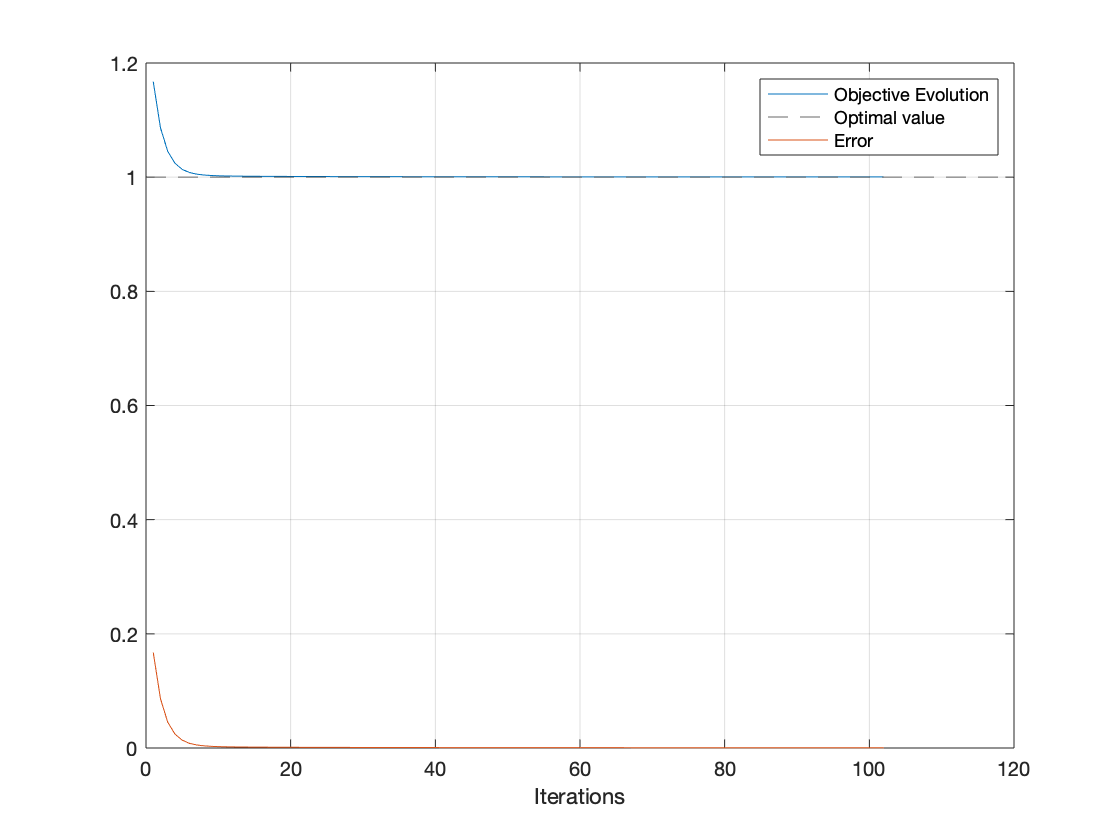

plot(obj_fb)
hold on
yline(1.0, '--');
hold on
plot( abs(1.0-obj_fb) );
legend('Objective Evolution','Optimal value','Error')
hold off 

grid on
xlabel('Iterations')

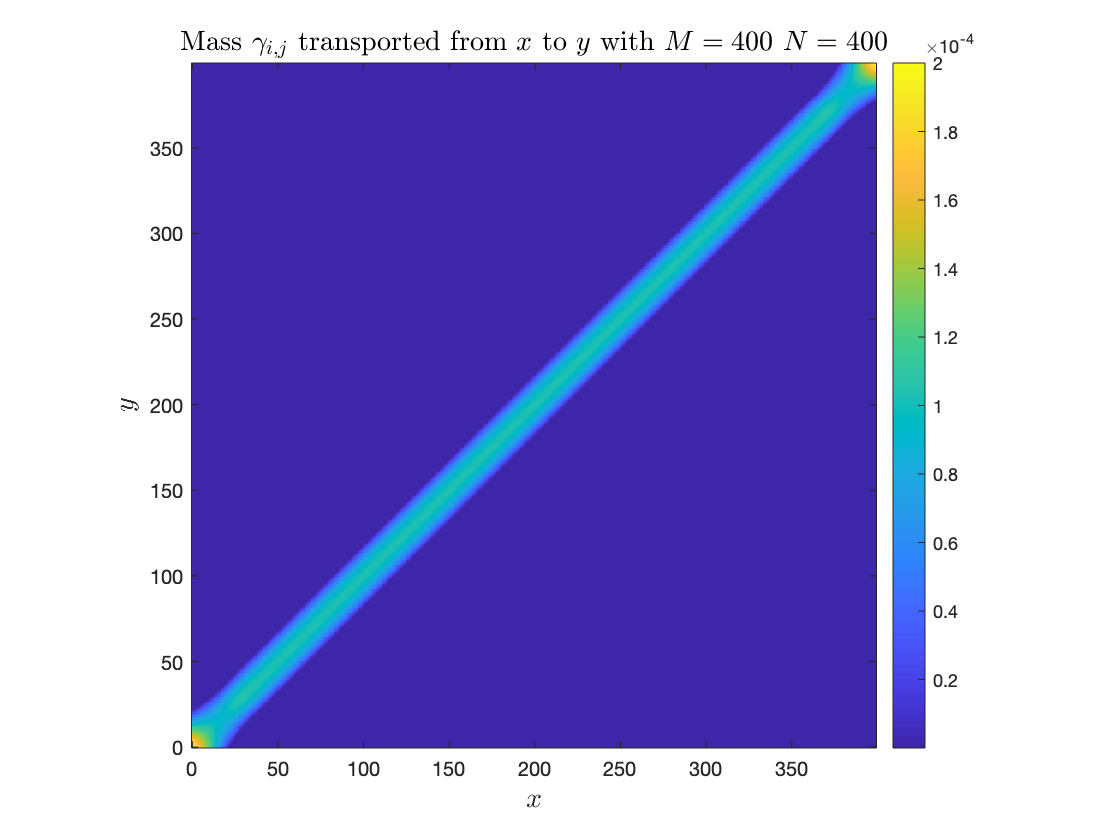

plotGamma(m,n,x_fb,M,N)

# FISTA

## Algorithm statement

Now we present an adapted FISTA to minimise $K$satisfying the constraints imposed by sets $C_1^m$ and $C_2^n$:

- Let $\varepsilon \in (0,\mu^{-1}).$

- Let $x_0 \in \mathbb{R}^{M\times N}$, $z_0 = x_0$, $t_0 = 1$.

- Select $\mu > 0$.

- **For **$k \in \{1, 2, \ldots\}$`:`

-     Define $y_{k} := z_{k-1} - \mu^{-1} c$.

-     Define $x_{k} := \mathrm{prox}_{\mu^{-1} \,\cdot \, \imath_C}(y_{k}) =  \mathrm{prox}_{\imath_C}(y_{k})$.

-     Define $t_k := \frac{1 + \sqrt{1 + 4 t^2_{k-1}} }{2}$.

-     Define $\lambda_k := 1 + \frac{t_{k-1}-1}{t_k }$

-     Define $z_k := x_{k-1} + \lambda_k ( x_{k} - x_{k-1} )$.

%% 
% Run algorithm
%%
[x_fi,obj_fi,temp_fi] = FISTA(c,m,n);
temp(end+1) = temp_fi;
obj(end+1)  = obj_fi;

Show results

plot(obj_fi)
hold on
yline(1.0, '--');
hold on
plot( abs(1.0-obj_fi) );
legend('Objective Evolution','Optimal value','Error')
hold off 

ans = 1×2 int16 row vector
   -2    2


# Primal dual

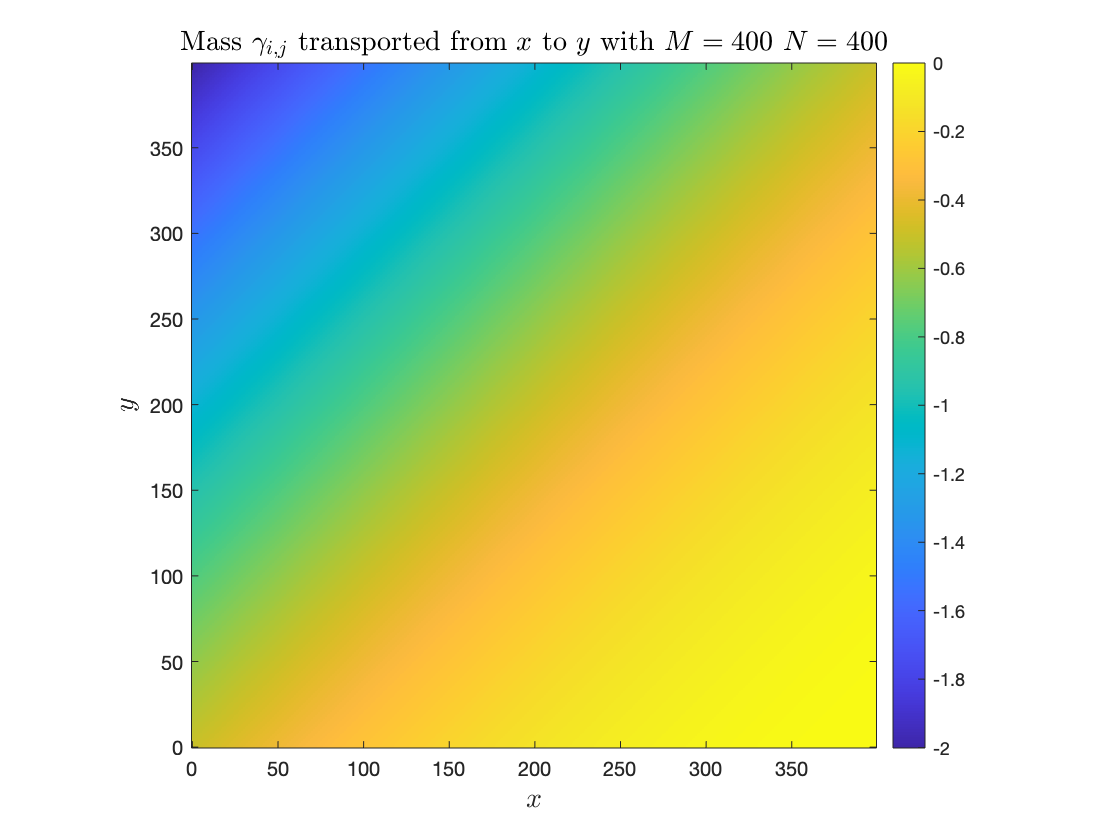

%% 
% Run algorithm
%%
[x_pd, obj_pd, y_1, y_2, temp_pd] = Primal_Dual(c, m, n, true, 5e-5);

temp(end+1) = temp_pd;
obj(end+1)  = obj_pd(end);

Store results

plotGamma(m,n,x_pd,M,N)

# Linear programming

% Lin progr system Ax = b
A = [kron( ones(1,N), speye(M) ); kron( speye(N), ones(1,M) )];
b = [ m;n ];
    
% Run algorithm
options = optimoptions('linprog','Algorithm','dual-simplex','OptimalityTolerance', 1e-4, 'ConstraintTolerance',1e-6);


Optimal solution found.



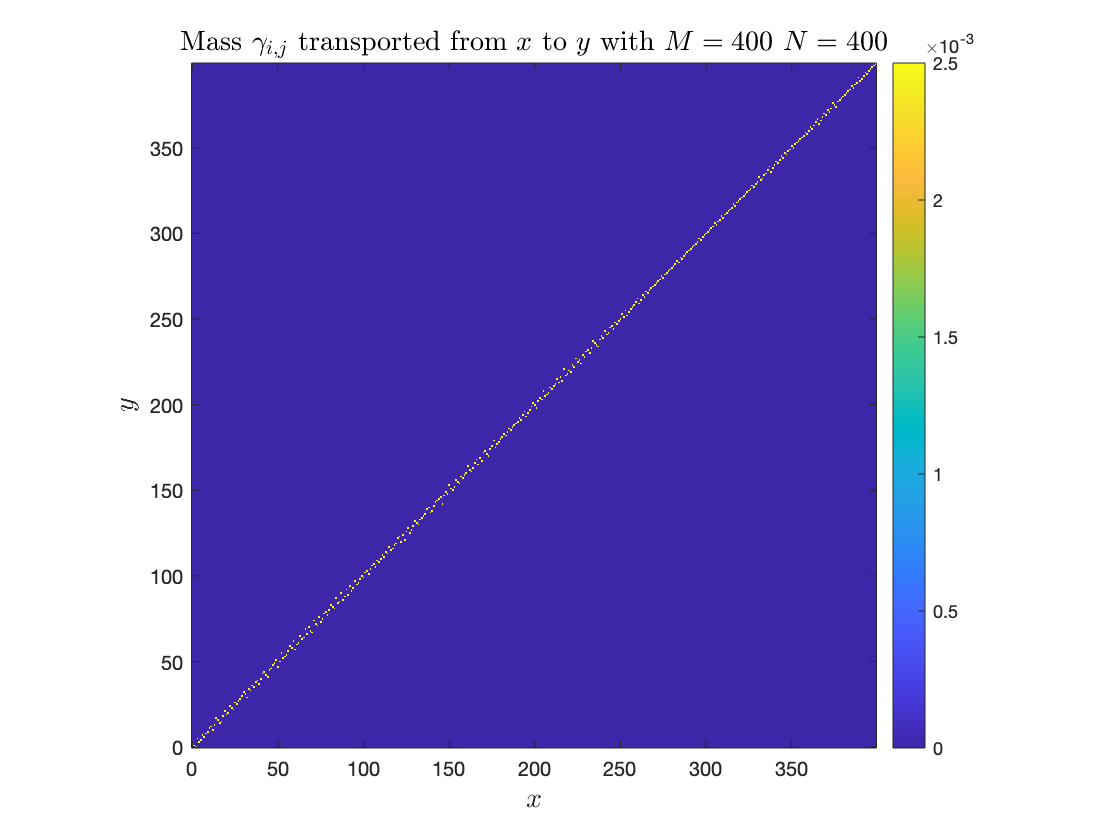

tStart = tic;
[x_lp,fval,exitflag,output,lambda] = linprog(c(:),[],[],A,b, sparse(zeros(N*M,1)), [], options);
temp(end+1) = toc(tStart);
obj(end+1) = sum(fval);

Display result

plotGamma(m,n,reshape(x_lp,M,N),M,N)

# Entropic Regularisation

% Perfomance values
eps = 0.0025; % Regularisation constant
verb = true;  % Return objective evaluation at each point
%% 
% Run algorithm
%%
[x_er,obj_er,temp_er] = Entropy_Regularisation(m,n,c,eps,verb);
temp(end+1) = temp_er;
obj(end+1)  = obj_er(end);

Show results

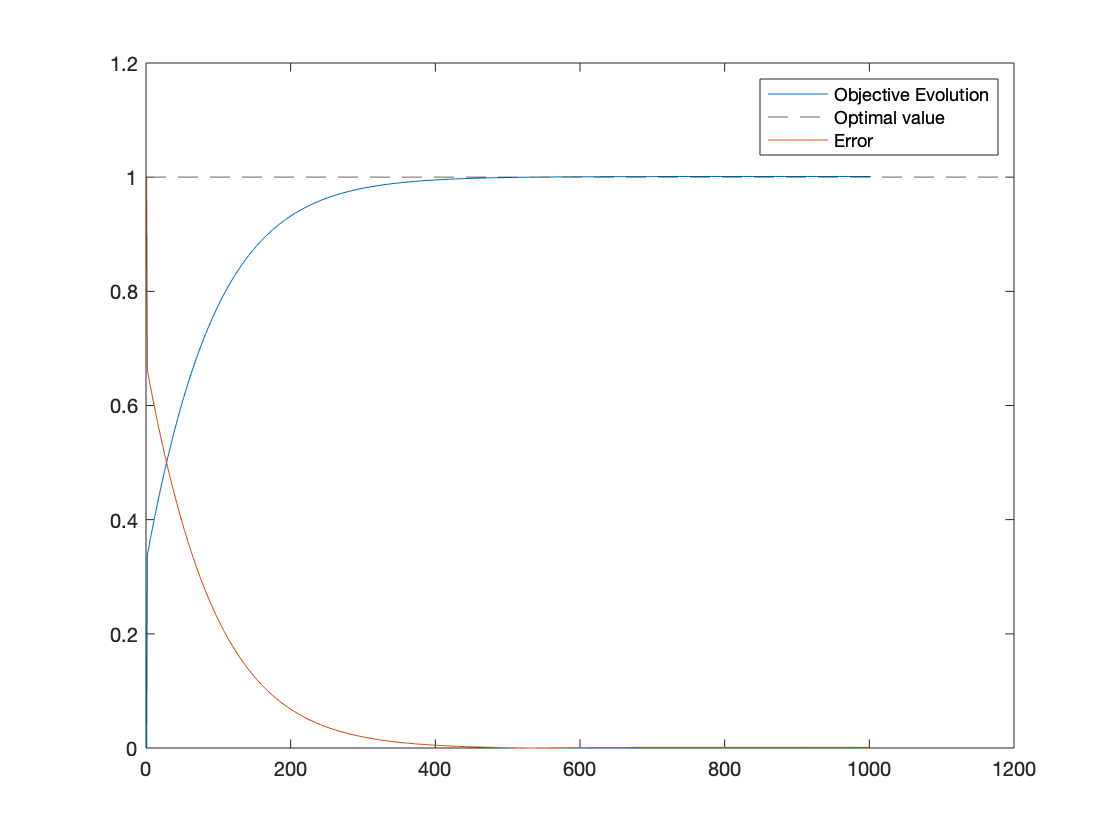

plot(obj_er)
hold on
yline(1.0, '--');

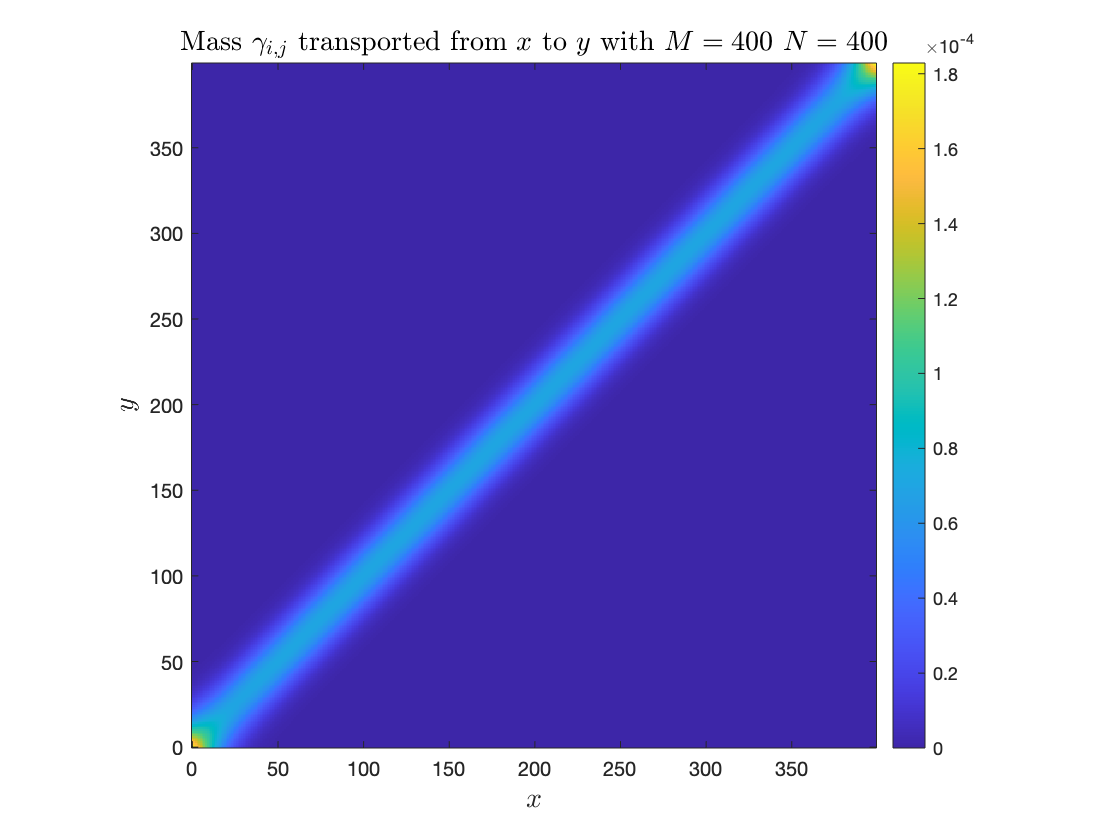

hold on

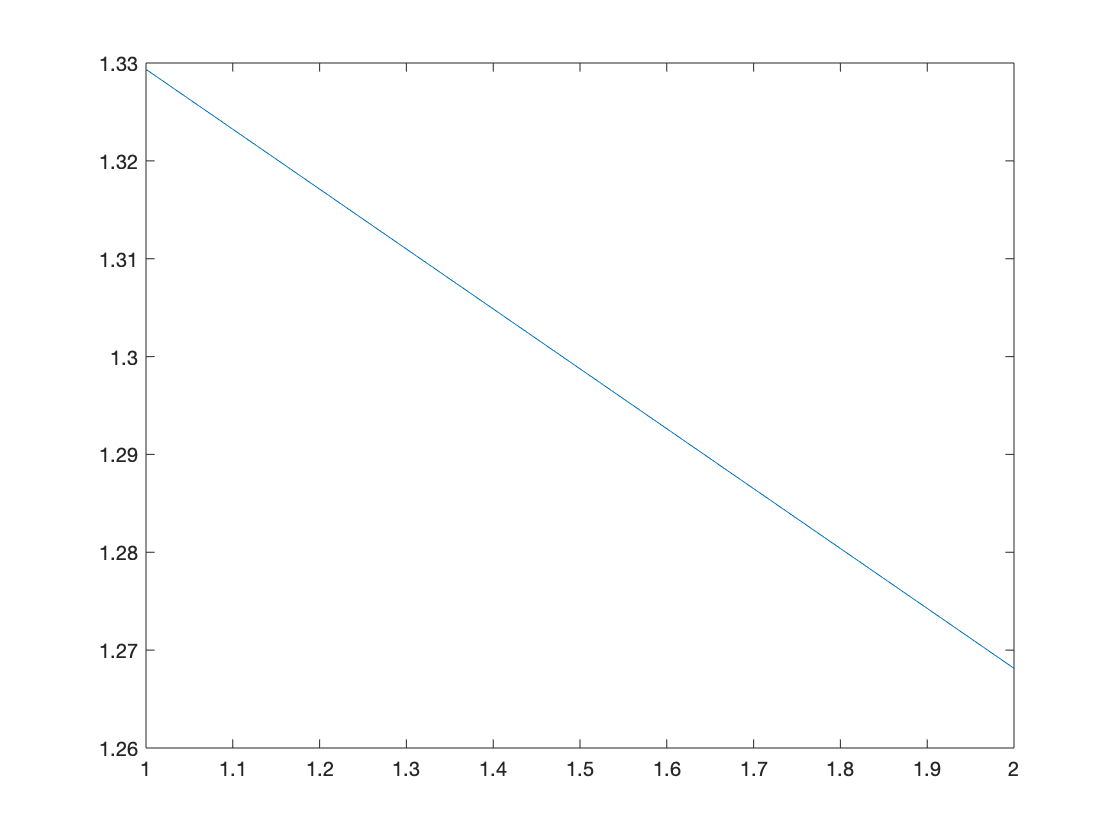

plot( abs(1.0-obj_er) );
legend('Objective Evolution','Optimal value','Error')

hold off 
plotGamma(m,n,x_er,M,N)

plot(temp)